cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_12_analyzeRealisticModel')
load('2018_08_12_aveSOS&steSOS_1-25')
load('rate_EMCLs')
load('transducer_2board')

r_num = t_num/2;
diff_point_each = zeros(r_num, length(aveSOS))

diff_point_each =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0    

for ii = 1:length(aveSOS)
    [Min ,ind] = min(tof_cell(101:200,:,ii),[],1);
    for jj = 1:length(diff_point_each)
        diff_point_each(jj,ii) = (ind(1,jj) - jj);
    end
end

とりあえず全到達点変化分のヒストグラムを表示させてみる．

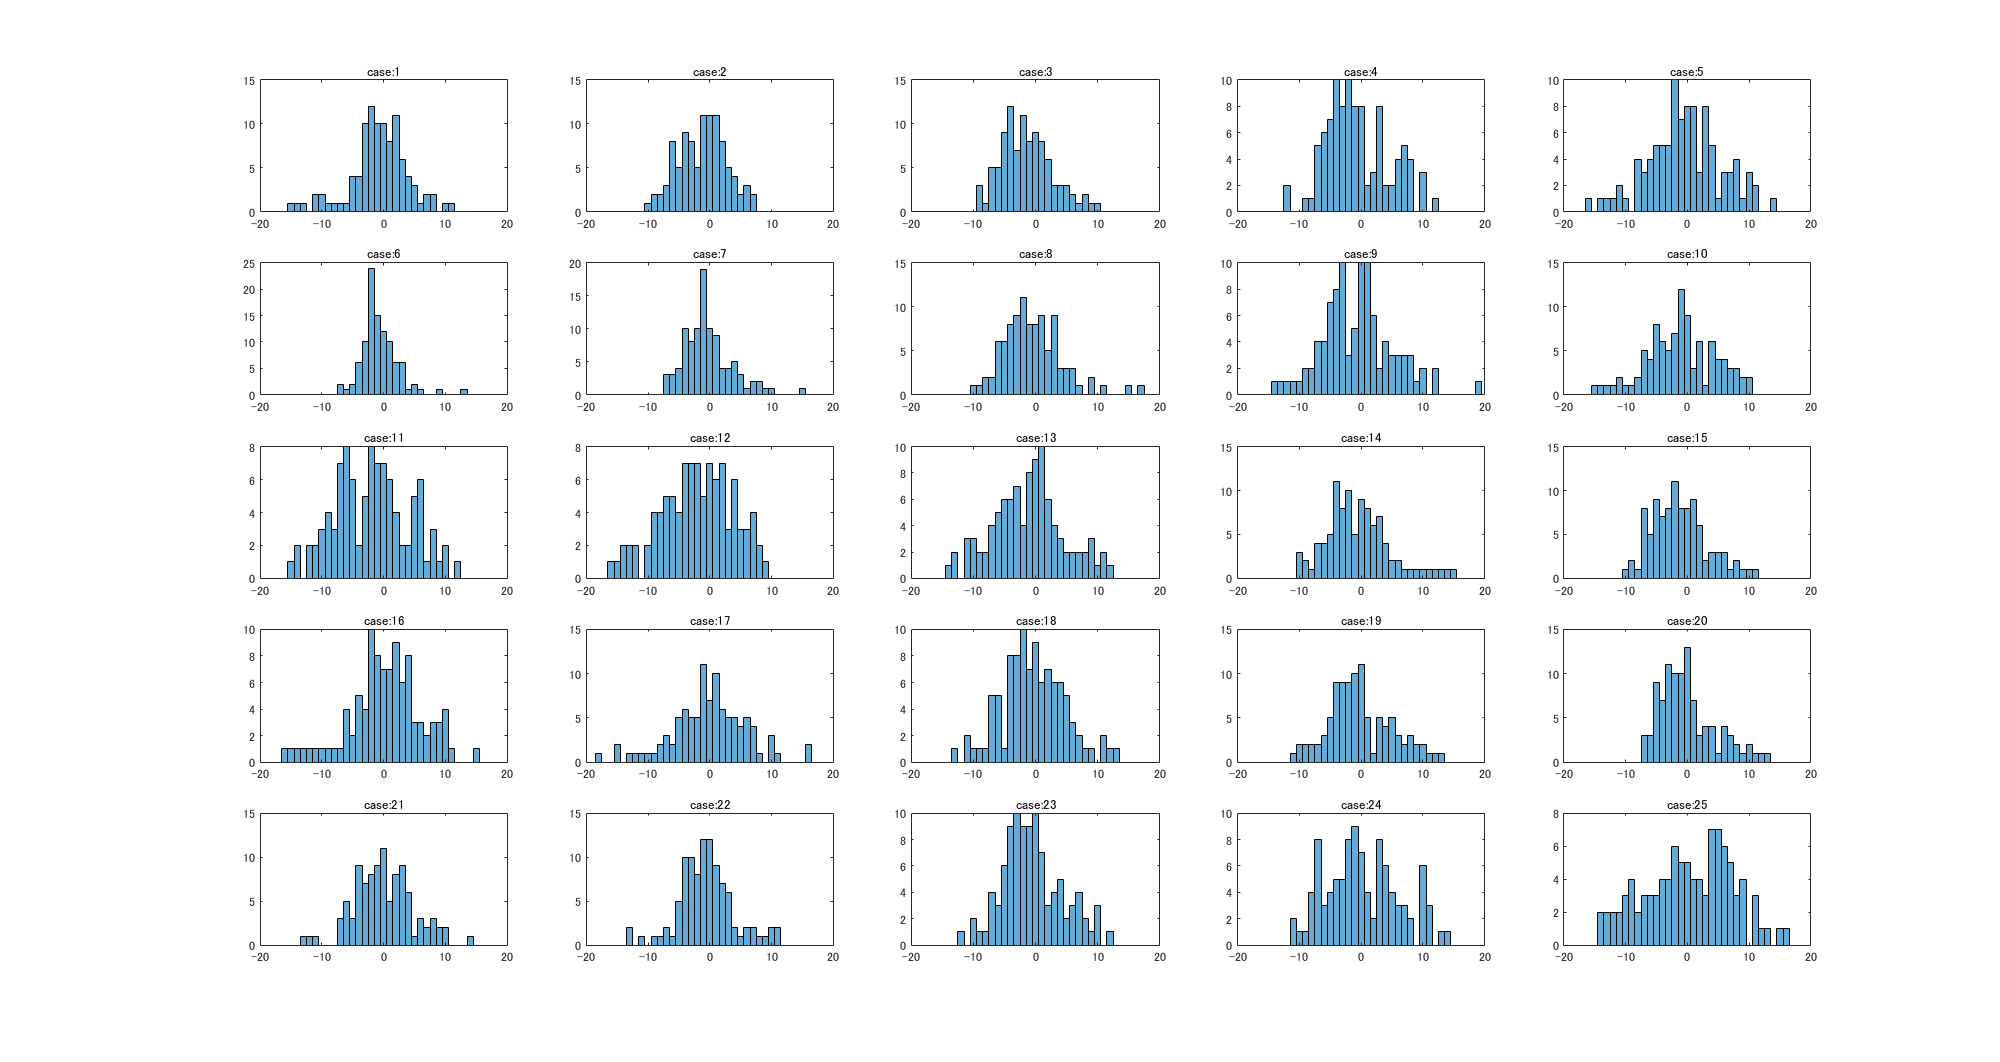

figure;
for i = 1:25
    subplot(5,5,i);
    histogram(diff_point_each(:,i));
    myfilename = sprintf('case:%d',i);
    title(myfilename);
    xlim([-20 20])
end

cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_24_displace_first_arrival_points')
myfilename = 'histogram_displace_points';
exportfig(myfilename,'png',[2000,2000]);

到達点変化の平均値を使うよりも，分散を用いた方が良さそう．

全部試してみればよい．

まずは経路変化分の分散(=y)をみる．

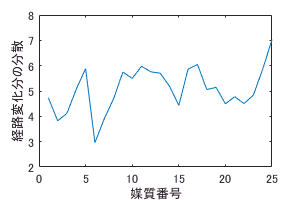

w = 1;
y = std(diff_point_each,w,1);
figure;
plot(y);
xlabel('媒質番号')
ylabel('経路変化分の分散')
cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_24_displace_first_arrival_points')
myfilename = 'dispersion_displace';
exportfig(myfilename,'png',[300,200]);

yの標準偏差syをみる．

w = 1;
sy = std(y,w,2)

sy = 0.8660

次に平均音速値xをみる．

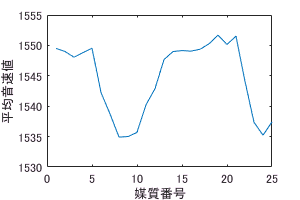

figure;
x = aveSOS2;
plot(aveSOS2);
xlabel('媒質番号')
ylabel('平均音速値')
cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_24_displace_first_arrival_points')
myfilename = 'ave_sos';
exportfig(myfilename,'png',[300,200]);

平均音速値xの標準偏差sxをみる．

w = 1;
sx = std(x,w,2)

sx = 5.8991

続いてEMCL占有率zをみる．

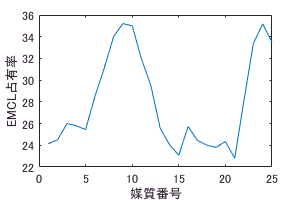

z = rate_EMCLs;
figure;
plot(z);
xlabel('媒質番号')
ylabel('EMCL占有率')
cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_24_displace_first_arrival_points')
myfilename = 'EMCL_rate';
exportfig(myfilename,'png',[300,200]);

EMCL占有率zの標準偏差szをみる．

w = 1;
sz = std(z,w,2)

sz = 4.2654

相関係数 x~y, y~z, z~xを出すにあたり，これらの散布図を用意する．

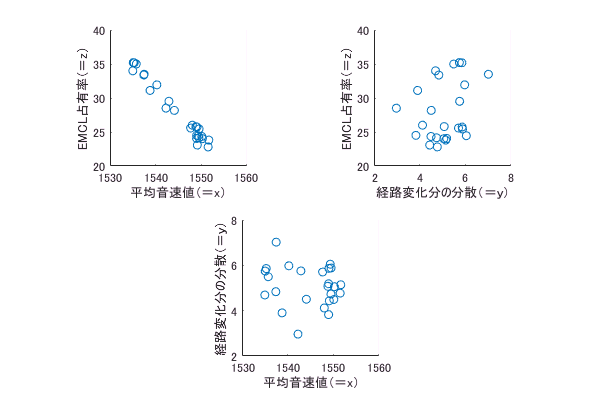

figure;
subplot(2,2,1);
scatter(x,z);
xlabel('平均音速値（＝x）')
ylabel('EMCL占有率（＝z）')
axis square;
subplot(2,2,2);
scatter(y,z);
xlabel('経路変化分の分散（＝ｙ）')
ylabel('EMCL占有率（＝z）')
axis square;
subplot(2,2,[3 4]);
scatter(x,y);
xlabel('平均音速値（＝x）')
ylabel('経路変化分の分散（＝ｙ）')
axis square;
hold off
cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_24_displace_first_arrival_points')
myfilename = 'correlations';
exportfig(myfilename,'png',[600,400]);

全変数の平均値を出す．

avex = mean(x)

avex = 1.5447e+03

avey = mean(y)

avey = 5.0839

avez = mean(z)

avez = 27.9704

全組み合わせの共分散を出す．

sxy = cov(x,y,w);
sxy = sxy(1,2)

sxy = -0.9103

szx = cov(z,x,w);
szx = szx(1,2)

szx = -24.8156

szy = cov(z,y,w);
szy = szy(1,2)

szy = 1.0086

sx2 = sx^2

sx2 = 34.7998

sy2 = sy^2

sy2 = 0.7500

sz2 = sz^2

sz2 = 18.1939

各変数同士の相関係数を求める．

rxy = sxy/(sx*sy)

rxy = -0.1782

rzx = szx/(sz*sx)

rzx = -0.9862

rzy = szy/(sz*sy)

rzy = 0.2730

２種類の回帰方程式(単回帰方程式と平面回帰方程式)とｘとの相関係数を比較する．

そのために重回帰方程式を求める．　z2 = ax + by + cとする．

単回帰方程式においてはすでにrzxで相関係数が出ている．

a = (szx*sy^2 - sxy*szy) / (sx^2*sy^2 - sxy^2)

a = -0.7001

b = (sx^2*szy - sxy*szx) / (sx^2*sy^2 - sxy^2)

b = 0.4950

c = (mean(z) - a*mean(x) - b*mean(y))

c = 1.1069e+03

z2 = a*x + b*y + c;
u = a*x + b*y;
szx

szx = -24.8156

szy

szy = 1.0086

sxy

sxy = -0.9103

rzu = sqrt((a*szx+b*szy)/sz^2)

rzu = 0.9912

重回帰方程式により推定精度の向上が確認された．bの符号が正であることに注目したい．

次に見てみたいものは，平均音速値を算出する際に用いる素子ペアごとの平均音速の分散性と経路変化分yの分散性がどのような相関を持っているか，ということである．おそらく平均音速の分散が大きいと経路不均一性が高くなるので経路変化分の分散もまた大きくなると見込まれる．これを確認することで，説明変数に従属変数と独立変数が混在した回帰方程式を誤ってつくることを回避する．

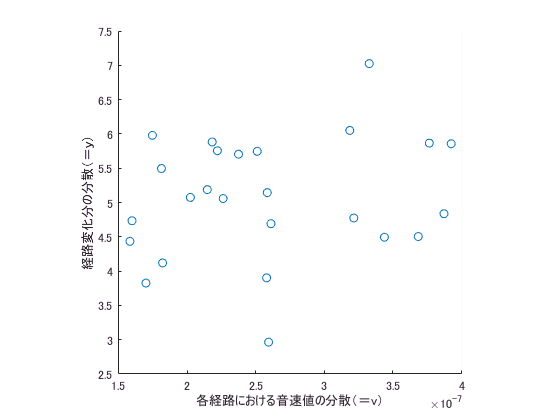

v_0 = zeros(100,25);%平均音速の分散を表すための行列
v = zeros(1,25);
for i = 1:25
    for j = 1:100
        v_0(j,i) = tof_cell(100+j,j,i);
    end
end
for i = 1:25
    v(1,i) = std(v_0(:,i),w,1);
end
figure;
scatter(v,y);
xlabel('各経路における音速値の分散（＝v）')
ylabel('経路変化分の分散（＝ｙ）')
axis square

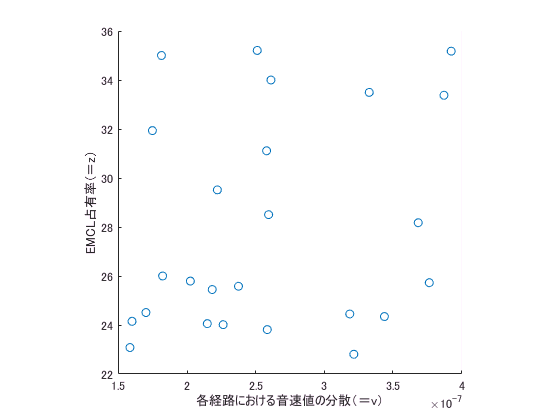

figure;
scatter(v,z);
xlabel('各経路における音速値の分散（＝v）')
ylabel('EMCL占有率（＝z）')
axis square

相関のかけらもなさそうだ．音速値の分散は媒質の速度不均一さに関連しているはず．

また，経路変化分の分散もまた速度不均一さに関連しているはず．

したがって，これら２つの指標は相関があるものと考えていたが，実際は違うもののように，独立性のある変数として認められる．

一応相関係数は出しておこう．

szv = cov(z,v,w);
szv = szv(1,2)

szv = 7.6416e-08

sz = std(z,w,2)

sz = 4.2654

sv = std(v,w,2)

sv = 7.3989e-08

rzv = szv/(sz*sv)

rzv = 0.2421

0.24と弱い相関があることがみとめられた．

相関が無くもない．やはりこのように小さな相関について議論する際にはたくさんのサンプルデータが必要である．500はほしいところだ．作ってしまおう．